# Residual Supply Index estimation of selected market participants

## Import the data

### Import the list of selected generators

load cleanedQMCTables.mat

### Import selected datetime and price

load selDateTimePriceISONE.mat;
selDateTimes = selDateTimePrice.DateTime;
selDates = selDateTimePrice.Date;
selHours = selDateTimePrice.Hour;
numSelDateTimes = size(selDateTimes, 1);

### Import ISONE hourly demand data

% Import ISONE hourly demand data in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

### Import generation capacity and Lerner Index data

load partCapTable.mat
load LernerPolyfitResults.mat

% Construct arrays of capacity and others' capacity
partCap = zeros(numParts, 1);
partIDs = categorical(partIDs);
partOtherCap = zeros(numSelParts, 1);
for n=1:numParts
    partCap(n) = partCapTable(partCapTable.PartID == partIDs(n), :).Capacity;
    partOtherCap(n) = partCapTable(partCapTable.PartID == partIDs(n), :).OtherCap;
end

## Calculate market share and residual supply index of all market participants

MS = zeros(numParts, numSelDateTimes); % Market share
RSI = zeros(numParts, numSelDateTimes); % Residual supply index
for dt=1:numSelDateTimes
    selDate = selDates(dt);
    selHour = selHours(dt);
    % Obtain total demand at the selected hour
    hourlyDemand = demandAll(demandAll.Date == selDate, :);    
    selHourDemand = hourlyDemand(hourlyDemand.Hour == selHour, :).DayAheadDemand;
    for n=1:numParts
        % Calcualte market share
        MS(n, dt) = min(partCap(n), selHourDemand)/selHourDemand;
        % Calculate residual supply index
        RSI(n, dt) = partOtherCap(n)/selHourDemand;
    end    
end

### Subset the results with seasons

selMonths = month(selDateTimes);
isSpring = ismember(month(selDateTimes), [3,4,5]);
isSummer = ismember(month(selDateTimes), [6,7,8]);
isAutumn = ismember(month(selDateTimes), [9,10,11]);
isWinter = ismember(month(selDateTimes), [12,1,2]);
MSSpring = MS(:, isSpring');
MSSummer = MS(:, isSummer');
MSAutumn = MS(:, isAutumn');
MSWinter = MS(:, isWinter');
RSISpring = RSI(:, isSpring');
RSISummer = RSI(:, isSummer');
RSIAutumn = RSI(:, isAutumn');
RSIWinter = RSI(:, isWinter');
priceArray = selDateTimePrice.averageLMP;
priceSpring = priceArray(isSpring);
priceSummer = priceArray(isSummer);
priceAutumn = priceArray(isAutumn);
priceWinter = priceArray(isWinter);
RSISeasons = {RSISpring, RSISummer, RSIAutumn, RSIWinter};
priceSeasons = {priceSpring, priceSummer, priceAutumn, priceWinter};

## Plot price vs RSI of all market participants

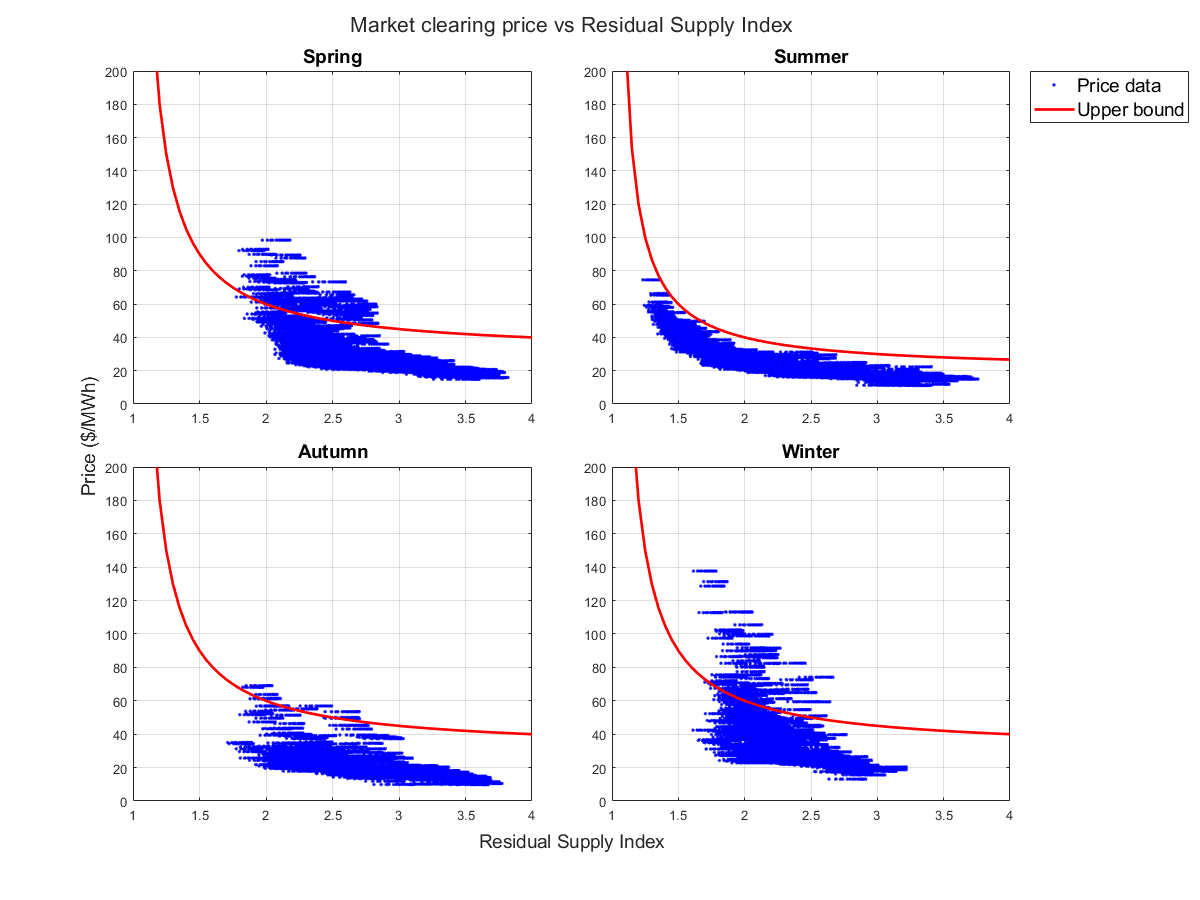

RS4Plot = 1:0.05:4;
LMCSpring = 30;
LMCSummer = 20;
LMCAutumn = 30;
LMCWinter = 30;
LMCSeasons = [LMCSpring; LMCSummer; LMCAutumn; LMCWinter];
Seasons = ["Spring"; "Summer"; "Autumn"; "Winter"];
t = tiledlayout(2,2,"TileSpacing","compact");
% Spring
for s=1:4
    nexttile;
    hold on;
    for n=1:numParts
        y = scatter(RSISeasons{s}(n, :), priceSeasons{s}, "b.");
    end
    priceUpper = (RS4Plot./(RS4Plot-1))*LMCSeasons(s);
    b = plot(RS4Plot, priceUpper, 'r-', "LineWidth",2);
    hold off; box on; grid on;
    title(Seasons(s), "FontSize", 14);
    axis([1, 4, 0, 200]);
    if s==2
        legend([y, b],["Price data", "Upper bound"], "Location","bestoutside", "FontSize", 14);
    end
end
xlabel(t, "Residual Supply Index", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize",  14);
title(t, "Market clearing price vs Residual Supply Index", "FontSize",  16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/RSIAll.png");

## Calculate MS, RSI, price upper bound and LI upper bound of selected market participants

selPartIdx = ismember(partIDs, categorical(selPartIDs));
selPartCap = partCap(selPartIdx);
selPartOtherCap = partOtherCap(selPartIdx);
selMSRSITables = cell(numSelParts, 1);
for n=1:numSelParts
    selLernerTable = selLernerFitTables{n};
    cleanedDates = selLernerTable.Date;
    cleanedHours = selLernerTable.Hour;
    % Create season index
    isSpring = ismember(month(selLernerTable.Date), [3,4,5]); 
    isSummer = ismember(month(selLernerTable.Date), [6,7,8]);
    isAutumn = ismember(month(selLernerTable.Date), [9,10,11]); 
    isWinter = ismember(month(selLernerTable.Date), [12,1,2]);
    Season = zeros(size(selLernerTable, 1), 1);
    Season(isSpring) = 1;
    Season(isSummer) = 2;
    Season(isAutumn) = 3;
    Season(isWinter) = 4;
    numCleanedDateTimes = size(cleanedHours, 1);
    selMS = zeros(numCleanedDateTimes, 1);
    selRSI = zeros(numCleanedDateTimes, 1);
    selLIUpper = zeros(numCleanedDateTimes, 1);
    selPriceUpper = zeros(numCleanedDateTimes, 1);
    selMC = selLernerTable.MCMarket;
    selLI = selLernerTable.LernerData;
    selPrice = selLernerTable.averageLMP;
    for dt=1:numCleanedDateTimes
        Date = cleanedDates(dt);
        Hour = cleanedHours(dt);
        hourlyDemand = demandAll(demandAll.Date == Date, :);    
        selHourDemand = hourlyDemand(hourlyDemand.Hour == Hour, :).DayAheadDemand;
        % Calcualte market share
        selMS(dt) = min(selPartCap(n), selHourDemand)/selHourDemand;
        % Calculate residual supply index
        selRSI(dt) = selPartOtherCap(n)/selHourDemand;
        % Calculate Lerner Index upper bound
        selLIUpper(dt) = selMS(dt)/(selMS(dt) + selRSI(dt) - 1);
        % Calculate price upper bound
        selPriceUpper(dt) = (1 + (selMS(dt)/(selRSI(dt) - 1)))*selMC(dt);
    end
    selMSRSITables{n} = table(cleanedDates, cleanedHours, Season, selLernerTable.Awarded, selMC, selMS, selRSI, selLI, selLIUpper, selPrice, selPriceUpper);
    selMSRSITables{n}.Properties.VariableNames = ["Date", "Hour", "Season", "Awarded", "MC", "MS", "RSI", "LI", "LIUpper", "Price", "PriceUpper"];
end

### Calculate statistics of the cleaned MC data

selMCSeasonalMedian = zeros(4, 4);
selMCSeasonalMean = zeros(4, 4);
selMCSeasonalMin = zeros(4, 4);
selMCSeasonalMax = zeros(4, 4);
for n=1:4
    for s=1:4
        selTable = selMSRSITables{n};
        selTableOneSeason = selTable(selTable.Season == s, :);
        selMCSeasonalMedian(n, s) = median(selTableOneSeason.MC);
        selMCSeasonalMean(n, s) = mean(selTableOneSeason.MC);
        selMCSeasonalMin(n, s) = min(selTableOneSeason.MC);
        selMCSeasonalMax(n, s) = max(selTableOneSeason.MC);
    end    
end

### Plot price vs RSI of selected market participants in 4 seasons

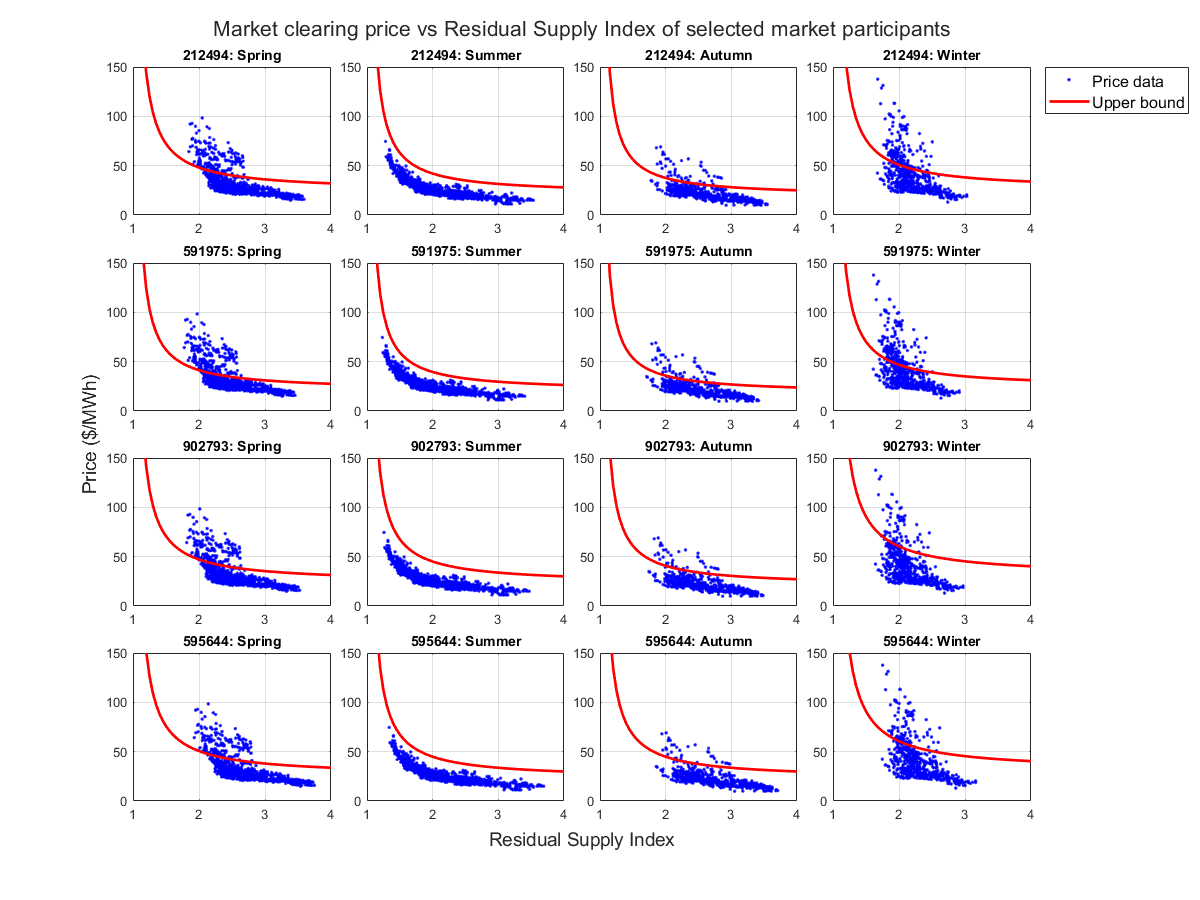

RS4Plot = 1:0.05:4;
LMCSeasons = selMCSeasonalMean;
Seasons = ["Spring"; "Summer"; "Autumn"; "Winter"];
t = tiledlayout(4,4,"TileSpacing","compact");
for n=1:4
    isSelPart = ismember(partIDs, categorical(selPartIDs(n)));
    for s=1:4
    nexttile;
    hold on;
    y = scatter(RSISeasons{s}(isSelPart, :), priceSeasons{s}, "b.");
    priceUpper = (RS4Plot./(RS4Plot-1))*LMCSeasons(n,s);
    b = plot(RS4Plot, priceUpper, 'r-', "LineWidth",2);
    hold off; box on; grid on;
    txt = sprintf("%s: %s", selPartIDs(n), Seasons(s));
    title(txt, "FontSize", 14);
    axis([1, 4, 0, 150]);
    if (s==4) && (n==1)
        legend([y, b],["Price data", "Upper bound"], "Location","bestoutside", "FontSize", 12);
    end
    end
end

xlabel(t, "Residual Supply Index", "FontSize", 14);
ylabel(t, "Price ($/MWh)", "FontSize",  14);
title(t, "Market clearing price vs Residual Supply Index of selected market participants", "FontSize",  16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/RSISel.png");